# Practico con utilitario 1

Se tiene una señal discreta y finita $x\left\lbrack n\right\rbrack$

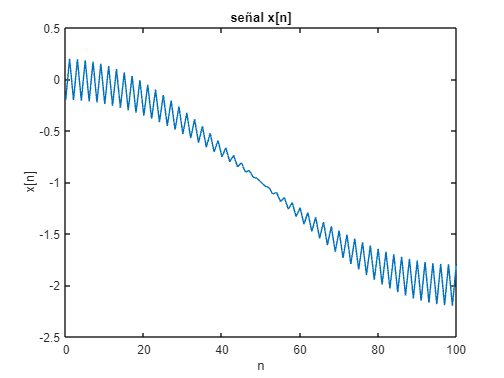

[n,x] = senial(748695);
plot(n,x);
title('señal x[n]');
xlabel('n');
ylabel('x[n]');

La señal parece estar compuesta por dos ondas, una de baja frecuencia con mayor amplitud y una de alta frecuencia y menor amplitud, ademas de un offset en continua de -1.

La señal de baja frecuencia parece completar medio periodo en una duracion de 100 muestras, por lo que se puede suponer que su periodo es $T=\;200$, y por lo tanto su frecuencia $s=\frac{1}{T}=\frac{1}{200}$. Tambien se puede ver que oscila entre 0 y -2 por lo que tiene una amplitud de 1

Grafico solo las 10 primeras muestras de la señal para poder ver la onda de alta frecuencia con mayor detalle 

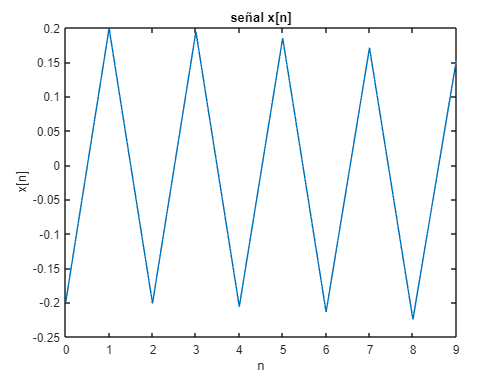

plot(n(1:10),x(1:10));
title('señal x[n]');
xlabel('n');
ylabel('x[n]');

La onda de alta frecuencia tiene un periodo $T=2$ y por lo tanto una frecuencia $\;s=\frac{1}{T}=\frac{1}{2}$. Se puede ver que la onda oscila entre -0.2 y 0.2, por lo que su amplitud es de 1/5

El offset de -1 obviamente tiene una frecuencia $s=0$

Lo que esperaria ver en la TFTD son tres deltas, en los valores de frecuencia $s=0$, $s=\frac{1}{200}$ y $s=\frac{1}{2}$

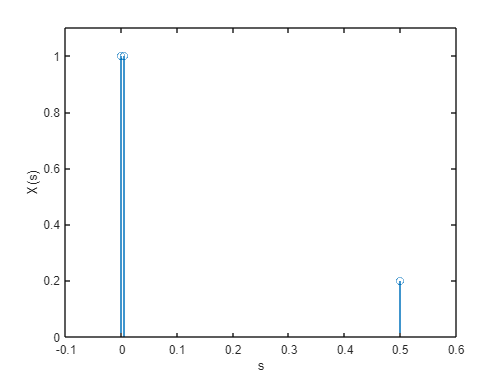

stem([0,0.005,0.5],[1,1,0.2]);
xlim([-0.1,0.6]);
ylim([0,1.1]);
xlabel('s');
ylabel('X(s)');

Devido a que x[n] es una señal de soporte finito, la **TFTD** que puedo calcular no es la de la señal que va de menos infinito a infinito, si no la de la señal por un cajon de soporte 101, que es la cantidad de muestras con la que cuenta la señal. Debido a esto, la tranformada no van a ser tres deltas, sino que ceran tren sincs centradas en estas deltas

## Tranformada de Fourier de la señal de tiempo discreto (TFTD)

La TFTD de una señal de soporte finito, se puede calcular como:

    
$$X\left(s\right)=\sum_{n=0}^k x\left\lbrack n\right\rbrack \times e^{-\textrm{j2}\pi \textrm{sn}}$$


donde ***k*** es el numero de muestras de la señal y ***s ***es la frecuencia normalizada.

$X\left(s\right)$ es una funcion periodica de periodo 1, por lo que solo la voy a graficar entre $s=-\frac{1}{2}$ y $s=\frac{1}{2}$  ya que mas alla de eso seria redundante. Tambien como ***s*** es una variable continua, para calcular la** TFTD** numericamente voy a usar valores discretos de ***s*** con un paso $\textrm{ds}=0\ldotp 0001$ 

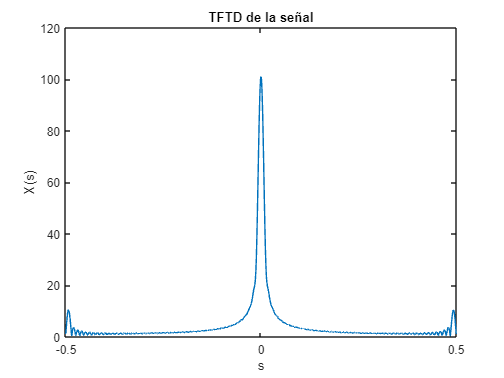

ds = 0.0001; s = -0.5:ds:0.5; senial_TFTD = zeros(1,length(s));

for i = 1:length(senial_TFTD)
    senial_TFTD(i) = sum(x.*exp(-1j*2*pi*s(i)*n));
end

figure
plot(s,abs(senial_TFTD));
title('TFTD de la señal')
xlabel('s')
ylabel('X(s)')

Antes predije tres sinc para tres frecuencias distintas, pero en el grafico solo se llegan a apreciar un pico en torno a $s=0$ y otro en torno a $s=\frac{1}{2}$. La razon de esta discrepancia probablemente sea porque que no tengo suficiente resolucion de frecuencia como para dicernir entre la sinc centrada en $s=0$ y la sinc centrada en $s=\frac{1}{200}$. Para poder dicernir entre ambas frecuencias necesitaria una mayor duracion de la señal, es decir un mayor numero de muestras.

## Sistemas descritos por ecuaciones de diferencias 

Se tienen cuatro señales descritas por las siguientes ecuaciones en diferencias:


$$y_1 \left\lbrack n\right\rbrack \;=\frac{1}{2}x\left\lbrack n\right\rbrack +\frac{1}{2}x\left\lbrack n-1\right\rbrack$$



$$y_2 \left\lbrack n\right\rbrack =\frac{1}{2}x\left\lbrack n\right\rbrack -\frac{1}{2}x\left\lbrack n-1\right\rbrack$$



$$y_3 \left\lbrack n\right\rbrack =\frac{1}{4}x\left\lbrack n\right\rbrack +\frac{1}{4}x\left\lbrack n-1\right\rbrack +\frac{1}{2}y_3 \left\lbrack n-1\right\rbrack$$



$$y_4 \left\lbrack n\right\rbrack =\frac{1}{4}x\left\lbrack n\right\rbrack +\frac{1}{4}x\left\lbrack n-1\right\rbrack -\frac{1}{2}y_4 \left\lbrack n-1\right\rbrack$$


### Respuesta en frecuencia de los sistemas

un sistema lineal e independiente en el tiempo puede caracterisarse a partir de su respuesta al impulso a partir de la siguiente ecuacion:

$y\left\lbrack n\right\rbrack =h\left\lbrack n\right\rbrack *x\left\lbrack n\right\rbrack$, 

Transformando esta exprecion se optiene:

$Y\left(s\right)=H\left(s\right)\times X\left(s\right)$, 

por lo tanto

 
$$H\left(s\right)=\frac{Y\left(s\right)}{X\left(s\right)}$$


Sistema 1


$$Y_1 \left(s\right)=\frac{1}{2}X\left(s\right)+\frac{1}{2}X\left(s\right)\times e^{-\mathrm{j2}\pi s\;}$$



$$\begin{array}{l}
Y_1 \left(s\right)=\frac{1}{2}X\left(s\right)\times \left(1+e^{-\mathrm{j2}\pi s} \right)\\
H_1 \left(s\right)=\frac{Y_1 \left(s\right)}{X\left(s\right)}=\frac{1}{2}\left(1+e^{-\mathrm{j2}\pi s} \right)
\end{array}$$


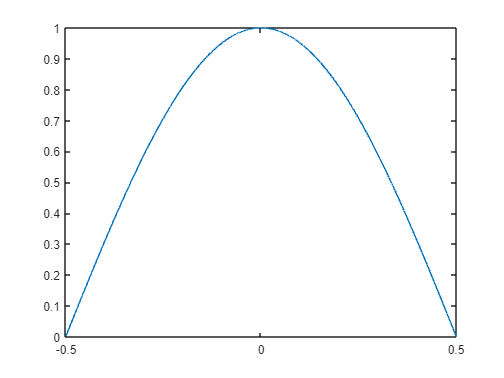

plot(s,abs(0.5 + 0.5*exp(-1j*2*pi*s)));

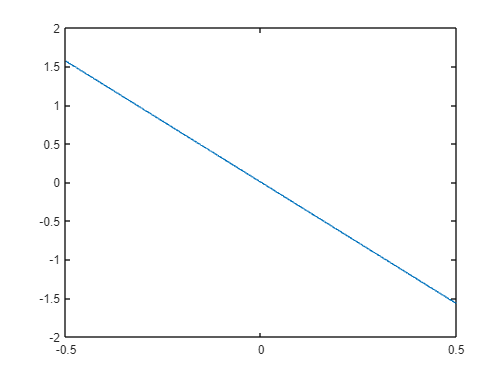

plot(s,angle(0.5 + 0.5*exp(-1j*2*pi*s)));

Sistema 2


$$Y_2 \left(s\right)=\frac{1}{2}X\left(s\right)-\frac{1}{2}X\left(s\right)\times e^{-\mathrm{j2}\pi s}$$



$$\begin{array}{l}
Y_2 \left(s\right)=\frac{1}{2}X\left(s\right)\times \left(1-e^{-\mathrm{j2}\pi s} \right)\\
H_2 \left(s\right)=\frac{Y_2 \left(s\right)}{X\left(s\right)}=\frac{1}{2}\left(1-e^{-\mathrm{j2}\pi s} \right)
\end{array}$$


Sistema 3


$$\begin{array}{l}
Y_3 \left(s\right)=\frac{1}{4}X\left(s\right)+\frac{1}{4}X\left(s\right)\times e^{-\mathrm{j2}\pi s} +\frac{1}{2}Y_3 \left(s\right)\times e^{-\mathrm{j2}\pi s} \\
Y_3 \left(s\right)-\frac{1}{2}Y_3 \left(s\right)\times e^{-\mathrm{j2}\pi s} =\frac{1}{4}X\left(s\right)+\frac{1}{4}X\left(s\right)\times e^{-\mathrm{j2}\pi s} \;\\
Y_3 \left(s\right)\left(1-\frac{1}{2}e^{-\mathrm{j2}\pi s} \right)=\frac{1}{4}X\left(s\right)\left(1+e^{-\mathrm{j2}\pi s} \right)\\
Y_3 \left(s\right)=\frac{1}{4}X\left(s\right)\left(1+e^{-\mathrm{j2}\pi s} \right)\times \frac{1}{\left(1-\frac{1}{2}e^{-\mathrm{j2}\pi s} \right)}\\
H_3 \left(s\right)=\frac{Y_3 \left(s\right)}{X\left(s\right)}=\frac{1}{4}\left(1+e^{-\mathrm{j2}\pi s} \right)\times \frac{1}{\left(1-\frac{1}{2}e^{-\mathrm{j2}\pi s} \right)}
\end{array}$$


Sistema 4


$$\begin{array}{l}
Y_4 \left(s\right)=\frac{1}{4}X\left(s\right)+\frac{1}{4}X\left(s\right)\times e^{-\mathrm{j2}\pi s} -\frac{1}{2}Y_4 \left(s\right)\times e^{-\mathrm{j2}\pi s} \\
Y_4 \left(s\right)+\frac{1}{2}Y_4 \left(s\right)\times e^{-\mathrm{j2}\pi s} =\frac{1}{4}X\left(s\right)+\frac{1}{4}X\left(s\right)\times e^{-\mathrm{j2}\pi s} \;\\
Y_4 \left(s\right)\left(1+\frac{1}{2}e^{-\mathrm{j2}\pi s} \right)=\frac{1}{4}X\left(s\right)\left(1+e^{-\mathrm{j2}\pi s} \right)\\
Y_4 \left(s\right)=\frac{1}{4}X\left(s\right)\left(1+e^{-\mathrm{j2}\pi s} \right)\times \frac{1}{\left(1+\frac{1}{2}e^{-\mathrm{j2}\pi s} \right)}\\
H_4 \left(s\right)=\frac{Y_4 \left(s\right)}{X\left(s\right)}=\frac{1}{4}\left(1+e^{-\mathrm{j2}\pi s} \right)\times \frac{1}{\left(1+\frac{1}{2}e^{-\mathrm{j2}\pi s} \right)}
\end{array}$$


### Respuesta al impulso 

Antitransformando $H\left(s\right)$ obtengo $h\left\lbrack n\right\rbrack$.

Sistema 1


$$H_1 \left(s\right)=\frac{1}{2}\left(1+e^{-\textrm{j2}\pi s} \right)$$


Antitranformando


$$h\left\lbrack n\right\rbrack =\frac{1}{2}\delta \left\lbrack n\right\rbrack +\frac{1}{2}\delta \left\lbrack n-1\right\rbrack$$


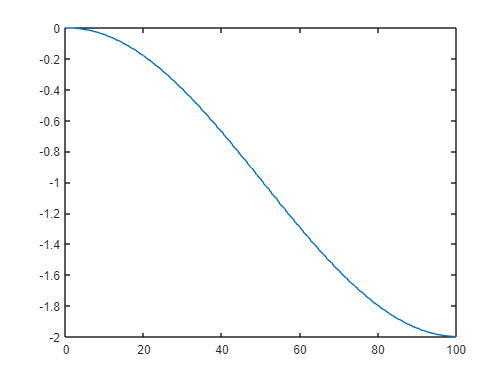

plot(n,y1(x))

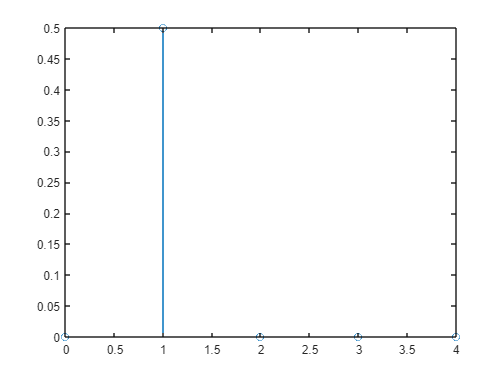

delta = zeros(1,length(x));
delta(1) = 1;
stem(n(1:5),y1(delta(1:5)));

function y = y1(x) 
y = zeros(1,length(x));
for n = 2:length(x)
    y(n) = 0.5*x(n) + 0.5*x(n-1);
end
end
